1)

R1 = 560;
R2 = 560;
R3 = 9e3;
C1 = 33e-3;
C2 = 33e-3;
C3 = 4.7e-6;


A = [-1/C1/R3, 0, -1/C1/R2;
     0, 0, -1/R1/C2;
     1/R1/C3, 1/R1/C3,-(1/R1/C3 + 1/R2/C3)]

A = 	1.0e+02 *

  -0.000033670033670                   0  -0.000541125541126
                   0                   0  -0.000541125541126
   3.799392097264438   3.799392097264438  -7.598784194528876


B = [1/R3/C1;
     0;
     0]

B =    0.003367003367003
                   0
                   0


C = [-1, -1, 0]

C =     -1    -1     0


D = 1

D =      1


format long
[numarator,numitor] = ss2tf(A,B,C,D)

numarator = 	1.0e+02 *

   0.010000000000000   7.598784194528876   0.411189620916066   0.000692238419051


numitor = 	1.0e+02 *

   0.010000000000000   7.598817864562545   0.436774752884181   0.000692238419051


2)

R1 = 560;
R2 = 560;
R3 = 9e3;
C1 = 33e-3;
C2 = 33e-3;
C3 = 4.7e-6;
H = tf(numarator,numitor)

H =
 
  s^3 + 759.9 s^2 + 41.12 s + 0.06922
  -----------------------------------
  s^3 + 759.9 s^2 + 43.68 s + 0.06922
 
Continuous-time transfer function.



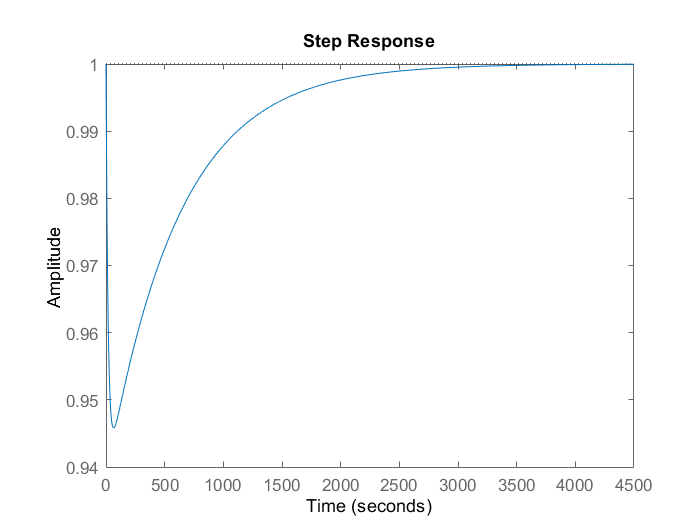

step(H)

3)

z = zero(H)

z = 	1.0e+02 *

  -7.598243031646676
  -0.000523768743012
  -0.000017394139187


p = pole(H)

p = 	1.0e+02 *

  -7.598243029248444
  -0.000558523546259
  -0.000016311767842


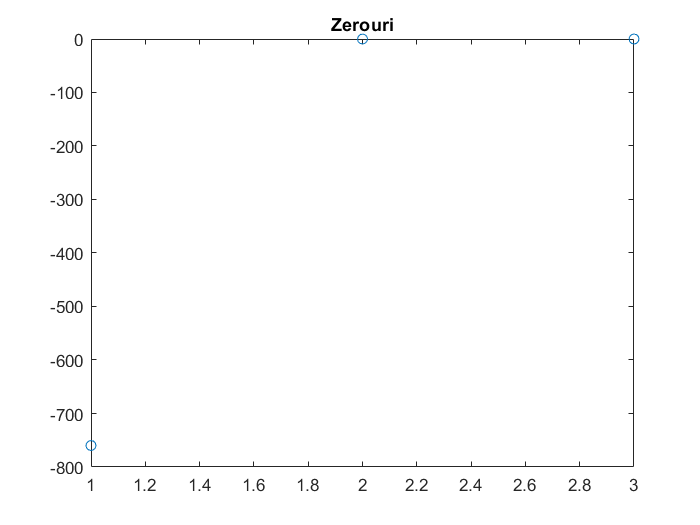

figure
plot(z,'o'), title("Zerouri")

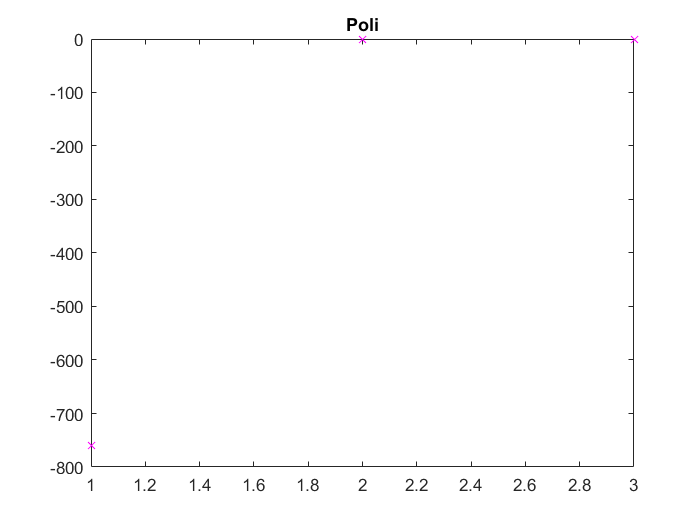

figure
plot(p,'mx'), title("Poli")

4)

format long
a2 = 1/R1/C3 + 1/R2/C3 + 1/R3/C1

a2 =      7.598817864562545e+02


a1 = 1/R1/R3/C1/C3 + 1/R2/R3/C1/C3 + 1/R1/R2/C1/C3 + 1/R1/R2/C2/C3

a1 =   43.677475288417533


a0 = 1/R1/R2/R3/C1/C2/C3

a0 =    0.069223841905061


b2 = -1/R3/C1

b2 =   -0.003367003367003


b1 = -(R1+R2)/R1/R2/R3/C1/C3

b1 =   -2.558513196811069


b0 = 0;
d = 1;

5)

format long
p_Markov = deconv([numarator,zeros(1,6)],numitor);
m_Hankle = [p_Markov(2) p_Markov(3) p_Markov(4);
            p_Markov(3) p_Markov(4) p_Markov(5);
            p_Markov(4) p_Markov(5) p_Markov(6)
            ]

m_Hankle = 	1.0e+04 *

  -0.000000336700337   0.000000001133660   0.000013844772796
   0.000000001133660   0.000013844772796  -0.010520416892992
   0.000013844772796  -0.010520416892992   7.993668478111492


        
det(m_Hankle)

ans =     -8.256042149634151e-05


6)

format short
A

A =    -0.0034         0   -0.0541
         0         0   -0.0541
  379.9392  379.9392 -759.8784


syms l
det(l*eye(3)-A)

$$ans = l^{3}+\frac{496286322806647661\,l^{2}}{653109906898944}+\frac{133122228489596761\,l}{3047846232195072}+\frac{13924919298074975}{201157851324874752}$$

7) Lyapunov

A

A =    -0.0034         0   -0.0541
         0         0   -0.0541
  379.9392  379.9392 -759.8784


A'

ans =    -0.0034         0  379.9392
         0         0  379.9392
   -0.0541   -0.0541 -759.8784


Q = eye(length(A))

Q =      1     0     0
     0     1     0
     0     0     1


P = lyap(A',Q)

P =   150.6750 -146.3250    0.0000
 -146.3250  169.4257   -0.0013
    0.0000   -0.0013    0.0007


eig(P)

ans =     0.0007
   13.4253
  306.6754


sys = ss(A,B,C,D)

sys =
 
  A = 
              x1         x2         x3
   x1  -0.003367          0   -0.05411
   x2          0          0   -0.05411
   x3      379.9      379.9     -759.9
 
  B = 
             u1
   x1  0.003367
   x2         0
   x3         0
 
  C = 
       x1  x2  x3
   y1  -1  -1   0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



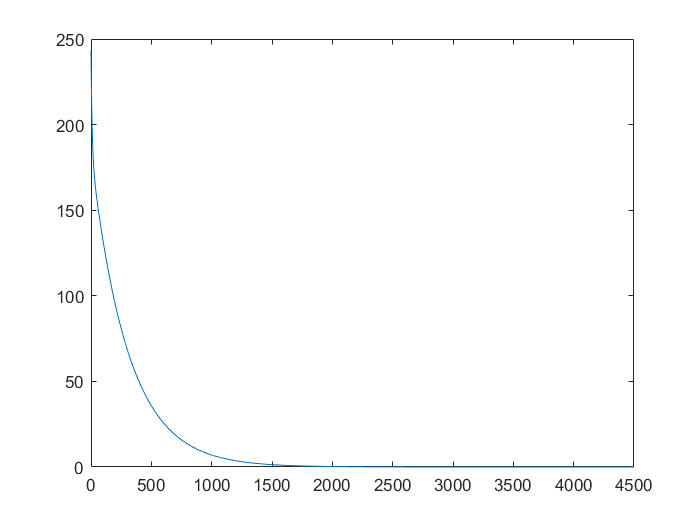

t1 = 0:0.01:4500;
u = zeros(1,length(t1));
[y,t1,x] = lsim(sys,u,t1,[1,2,3]);

V = zeros(1,length(t1));

for i = 1:length(t1)
   V(i)= x(i,:) *P*x(i,:)'; 
end

plot(t1,V)

8)

format long
[r1,p1,k1] = residue(numarator,numitor)

r1 =    0.000000239824425
  -0.003468542519523
   0.000101299328237


p1 = 	1.0e+02 *

  -7.598243029248444
  -0.000558523546259
  -0.000016311767842


k1 =      1


syms s
F = (s^3+759.9*s^2+41.12*s+0.069)/(s^3+759.9*s^2+43.68*s+0.069);
h = vpa(ilaplace(F),3)

$$h = 0.00337\,{\mathrm{e}}^{-760.0\,t}+1.01e-4\,{\mathrm{e}}^{-0.00163\,t}-0.00347\,{\mathrm{e}}^{-0.0559\,t}+\delta (t)$$

format long
[r2,p2,k2]=residue(numarator,[numitor,0])

r2 =   -0.000000000315631
   0.062101992704765
  -0.062101992388937
   0.999999999999803


p2 = 	1.0e+02 *

  -7.598243029248444
  -0.000558523546259
  -0.000016311767842
                   0



k2 =

     []



F1 = (s^3+759.9*s^2+41.12*s+0.069)/(s^4+759.9*s^3+43.68*s^2+0.069*s);
y1 = vpa(ilaplace(F1),3)

$$y1 = 0.0621\,{\mathrm{e}}^{-0.0559\,t}-0.0621\,{\mathrm{e}}^{-0.00163\,t}-4.43e-6\,{\mathrm{e}}^{-760.0\,t}+1.0$$

format long
[r3,p3,k3]=residue(numarator,[numitor,0,0])

r3 =    0.000000000000415
  -1.111895695726638
  38.071895695586946
 -36.959999999860592
   0.999999999999803


p3 = 	1.0e+02 *

  -7.598243029248444
  -0.000558523546259
  -0.000016311767842
                   0
                   0



k3 =

     []



F2 = (s^3+759.9*s^2+41.12*s+0.069)/(s^5+759.9*s^4+43.68*s^3+0.069*s^2);
y2 = vpa(ilaplace(F2),3)

$$y2 = t+5.3e-9\,{\mathrm{e}}^{-760.0\,t}+38.2\,{\mathrm{e}}^{-0.00163\,t}-1.11\,{\mathrm{e}}^{-0.0559\,t}-37.1$$

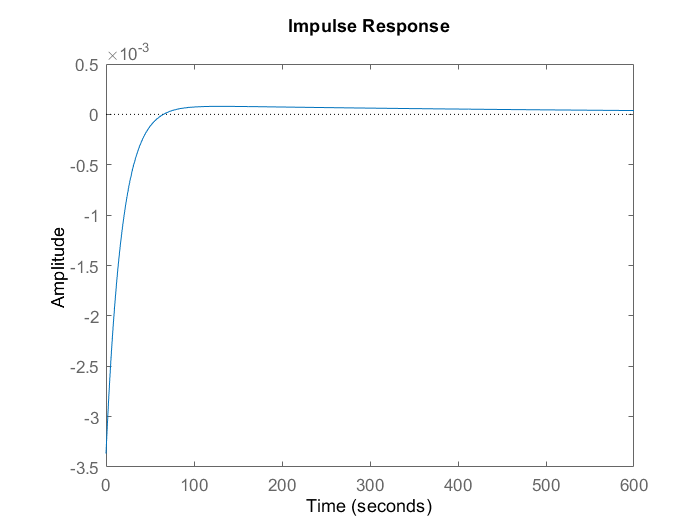

figure 
impulse(H)

figure
step(H)

H1 = tf([1,759.9,41.12,0.069],[1,759.9,43.68,0.069,0])

H1 =
 
    s^3 + 759.9 s^2 + 41.12 s + 0.069
  -------------------------------------
  s^4 + 759.9 s^3 + 43.68 s^2 + 0.069 s
 
Continuous-time transfer function.



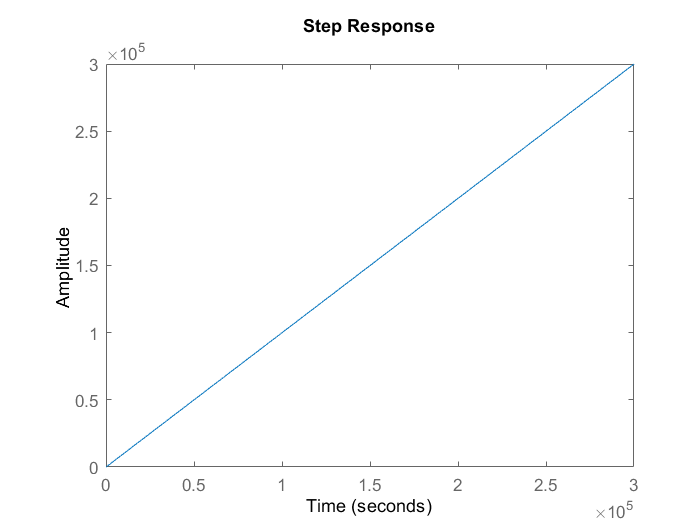

figure
step(H1)

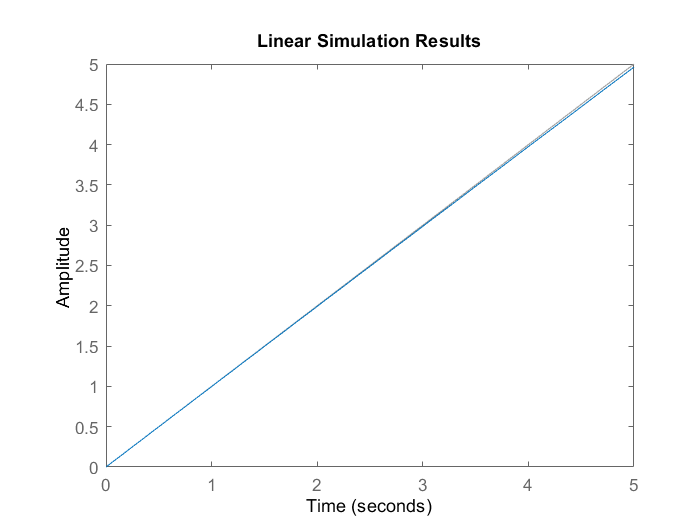

t=0:0.01:5;
u = t;
lsim(H,u,t)

9)

H2 = zpk(H)

H2 =
 
  (s+759.8) (s+0.05238) (s+0.001739)
  ----------------------------------
  (s+759.8) (s+0.05585) (s+0.001631)
 
Continuous-time zero/pole/gain model.



1/(-z(1))

ans =    0.001316093728294


1/(-z(2))

ans =   19.092395515055401


1/(-z(3))

ans =      5.749062883909887e+02


1/(-p(1))

ans =    0.001316093728709


1/(-p(2))

ans =   17.904348110255068


1/(-p(3))

ans =      6.130543357956568e+02


10)

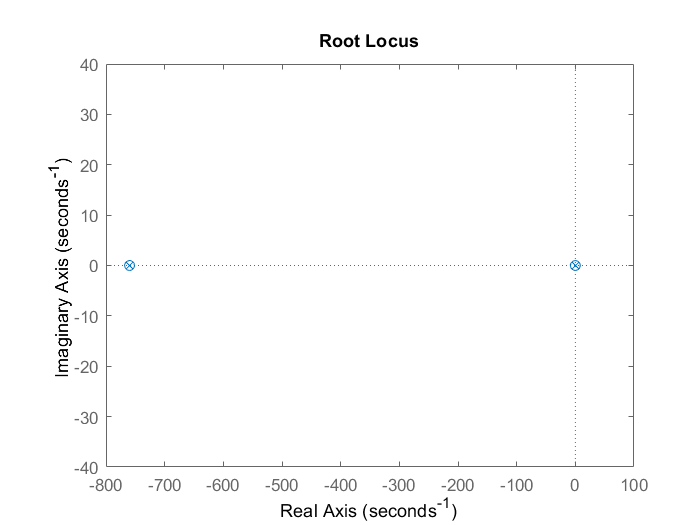

rlocus(H)

11)

numaratorDes=[1,759.9,41.12,0.069,0];
numitorDes = [1,761.9,1563.68,84.869,0.138];
Hdes = tf(numaratorDes,numitorDes)

Hdes =
 
     s^4 + 759.9 s^3 + 41.12 s^2 + 0.069 s
  --------------------------------------------
  s^4 + 761.9 s^3 + 1564 s^2 + 84.87 s + 0.138
 
Continuous-time transfer function.



pDes = pole(Hdes)

pDes = 	1.0e+02 *

  -7.598422461501188
  -0.020020088593982
  -0.000540671280354
  -0.000016778624478


zDes=zero(Hdes)

zDes = 	1.0e+02 *

                   0
  -7.598458838824237
  -0.000523825658373
  -0.000017335517391


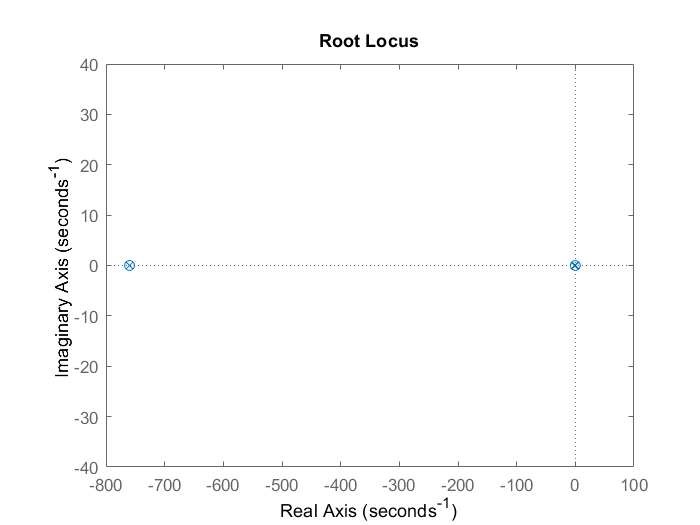

rlocus(Hdes)